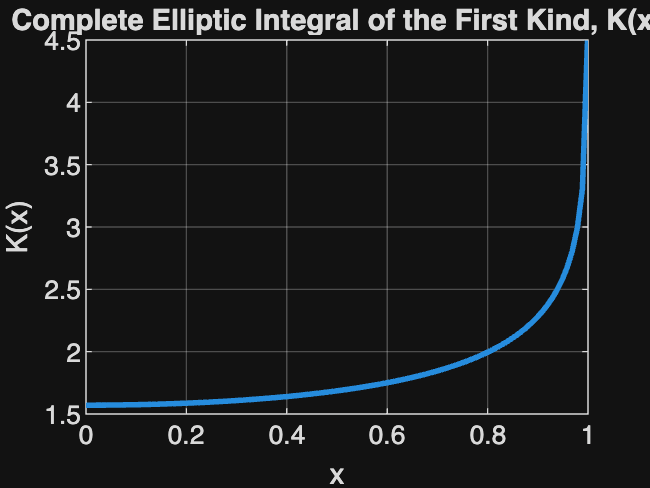

x_vals=linspace(0,0.999,100);
k_vals=zeros(size(x_vals));

for i=1:length(x_vals)
    x=x_vals(i);
    f = @(theta) 1 ./ sqrt(1 - (x^2) * sin(theta).^2);
    k_vals(i)=integral(f,0,pi/2);
end
figure;
plot(x_vals, k_vals, 'LineWidth', 2);
title('Complete Elliptic Integral of the First Kind, K(x)');
xlabel('x');
ylabel('K(x)');
grid on;